# Import Audio

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1 & 3

The signal that you'll watermark in this module is a recording of a flute playing one note. Before you watermark the signal, you can visualize the signal in this activity.

Recall that you can import audio files into with `audioread`, using separate variables for the signal data and the sample rate:

`[``sig``,``fs``]` `=` `audioread``(``"``filename``"``)`

To see which file formats are supported, check [the documentation](https://www.mathworks.com/help/matlab/ref/audioread.html#btiabil-1-filename).

The end of the signal has a large amplitude sound. It makes it difficult to see the rest of the signal.

You can extract portions of a signal using array indexing:

`sig` `=` `sig``(``n``:``m``)`

where `n` and `m` are the starting and ending indices, respectively.

To get the first `k` seconds of audio, you can use the sample rate to calculate the ending index:

`sig` `=` `sig``(``1``:``k``*``fs``)`

[flute, fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:7*fs)

flute =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Task 2

A strip plot is a wraparound plot that's convenient for viewing the entire duration of a signal.

`strips``(``sig``,``n``,``fs``)`

`n` is the number of seconds per strip and `fs` is the sample rate.

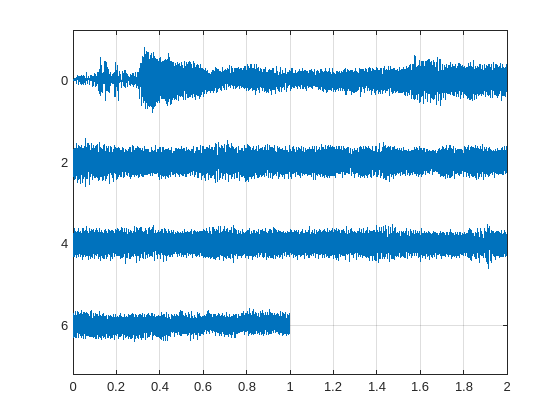

strips(flute, 2, fs)
grid on

## Task 4

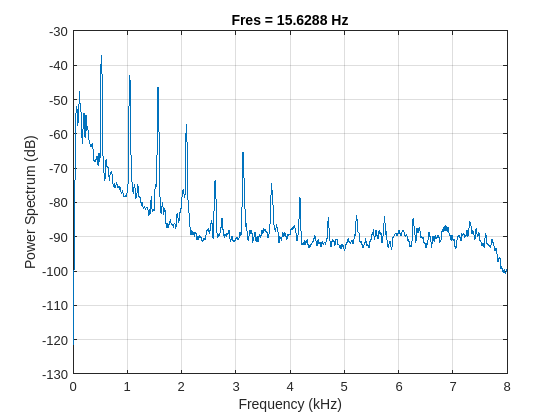

pspectrum(flute, fs)